## Introduction

This document demonstrates the use of the DoptFracPoly function to find D-optimal designs for fractional polynomials in logistic regression.

Start with a standard polynomial, $1 + x + x^2$. We must specify nominal coefficient values, the powers on x, the number of design points, and whether to calculate the sensitivity function.

beta = [1,1,1];
powers = [1, 2];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

At the end of the console output, the optimal design is displayed along with the values of the sensitivity function at the design points. The function will also plot the sensitivity function for the design found.

Now suppose we want to find the optimal design for $1 + x^{-1} + \sqrt{x}$. All we need to do is to change the powers vector.

beta = [1,1,1];
powers = [-1, 0.5];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

## Examples of Designs

In their original paper, Royston and Altman give two applied examples of logistic regression using fractional polynomials. In both cases, they find the best values of the powers so that the model fits the data opitmally. The final regression coefficients are unknown. Therefore, we will find optimal designs for the two sets of powers and experiment with different values for the regression coefficients.

### In Vitro Fertilization example, p = (-1, 1)

powers = [-1, -1];

% simple case
% sensitivity function has trouble with matrix inverse
beta = [1,1,1];
pts = 4;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.06s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.18s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.28s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.31s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

-1.180702 

-1.421591 

-0.533525 


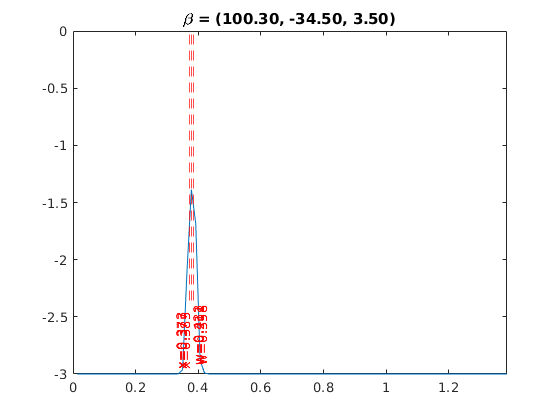

% more complicated case
% same problem
beta = [100.3,-34.5,3.5];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

The problem seems to be with repeated powers. Fractional polynomials introduce a log multiple for repeated powers that may be causing some issues.

### Myelomatosis example, p = (-2, 3)

The model used for this example from Royston and Altman included other covariates, but it is still interesting to look at the fractional polynomial in isolation.

powers = [-2, 3];

GA on 1-objective 6-variable UserProblem (  0.50%), 0.03s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.06s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.10s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.13s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.29s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

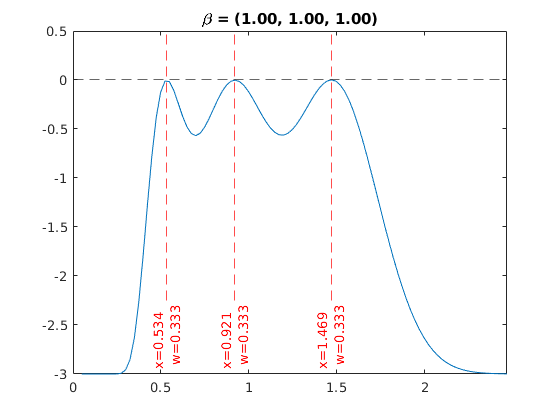

% simple case
beta = [1,1,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.26s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.29s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.37s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

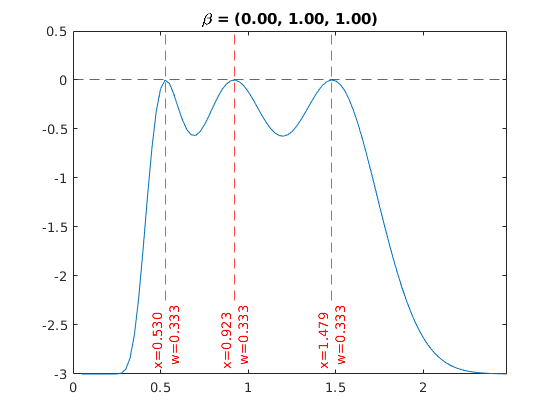

% beta0 = 0
beta = [0,1,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 8-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 8-variable UserProblem (  1.50%), 0.05s passed...
GA on 1-objective 8-variable UserProblem (  2.50%), 0.08s passed...
GA on 1-objective 8-variable UserProblem (  3.50%), 0.11s passed...
GA on 1-objective 8-variable UserProblem (  4.50%), 0.13s passed...
GA on 1-objective 8-variable UserProblem (  5.50%), 0.16s passed...
GA on 1-objective 8-variable UserProblem (  6.50%), 0.19s passed...
GA on 1-objective 8-variable UserProblem (  7.50%), 0.21s passed...
GA on 1-objective 8-variable UserProblem (  8.50%), 0.24s passed...
GA on 1-objective 8-variable UserProblem (  9.50%), 0.26s passed...
GA on 1-objective 8-variable UserProblem ( 10.50%), 0.29s passed...
GA on 1-objective 8-variable UserProblem ( 11.50%), 0.31s passed...
GA on 1-objective 8-variable UserProblem ( 12.50%), 0.33s passed...
GA on 1-objective 8-variable UserProblem ( 13.50%), 0.36s passed...
GA on 1-objective 8-variable UserProblem ( 14.50

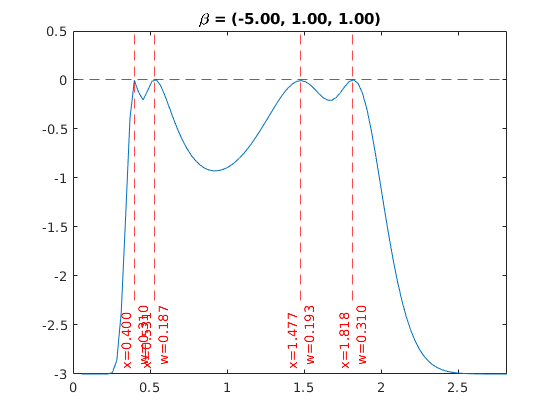

% beta0 < 0 
% this is now a 4 point design
beta = [-5,1,1];
pts = 4;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.07s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.28s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.37s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

-0.127638 

0.379412 

-0.190577 


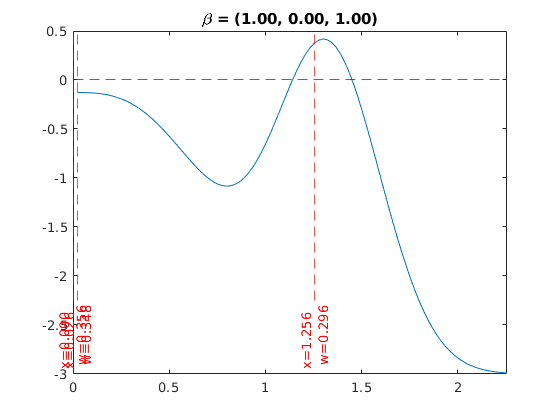

% beta1 = 0
% matrix inverse trouble
beta = [1,0,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.13s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.18s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.25s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.28s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

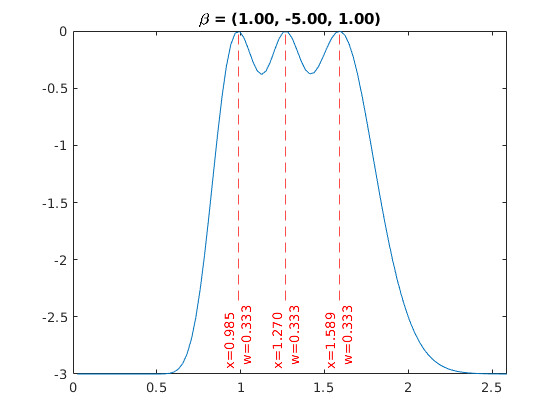

% beta1 < 0
beta = [1,-5,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.06s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.13s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.26s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.29s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.31s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

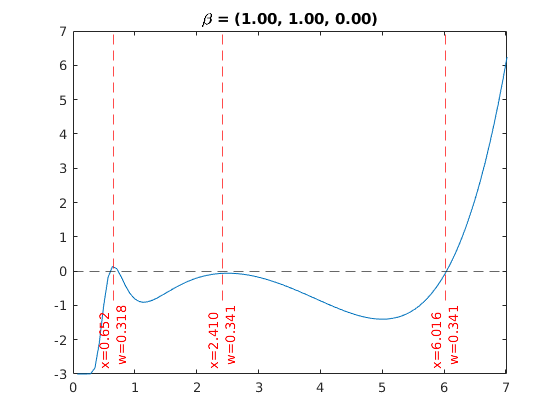

% beta2 = 0
beta = [1,1,0];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.27s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.37s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

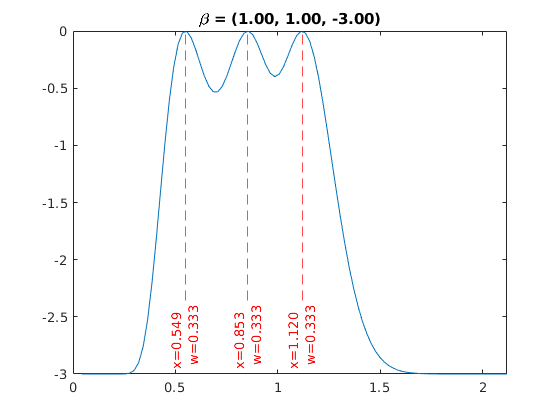

% beta2 <0
beta = [1,1,-3];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.03s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.07s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.22s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.28s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

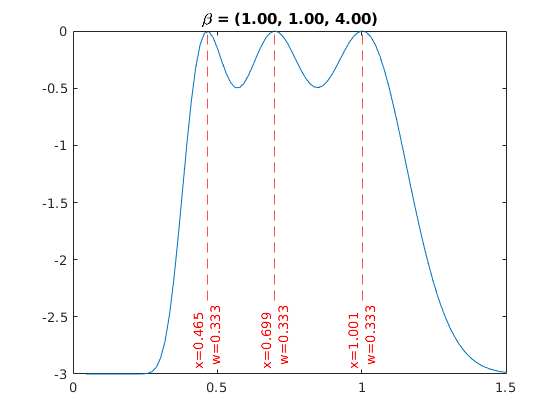

% beta2 > 1
beta = [1,1,4];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

GA on 1-objective 6-variable UserProblem (  0.50%), 0.02s passed...
GA on 1-objective 6-variable UserProblem (  1.50%), 0.06s passed...
GA on 1-objective 6-variable UserProblem (  2.50%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.50%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.50%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.50%), 0.18s passed...
GA on 1-objective 6-variable UserProblem (  6.50%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.50%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  8.50%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  9.50%), 0.28s passed...
GA on 1-objective 6-variable UserProblem ( 10.50%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 11.50%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 12.50%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 13.50%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 14.50

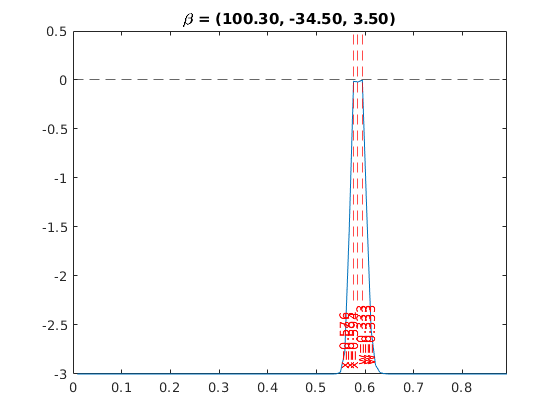

% same complicated case from last example
% also a single peak
beta = [100.3,-34.5,3.5];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens);

Setting p = (-2, 3) seems to result in mostly equally weighted 3 point designs. Like for quadratic models, setting the intercept a negative value seems to produce a 4 point design. Again, similar to the quadratic case, the 3 point designs seem to be equally weighted and the 4 point designs seem to be symmetrically weighted.